# [Scale Data for Machine Learning](https://apmonitor.com/pds/index.php/Main/ScaleData)

Scaling (inputs and outputs) can improve the training process for machine learning. Certain types of classifiers do not improve with data scaling. These include [Decision Trees](https://apmonitor.com/pds/index.php/Main/DecisionTree), [RandomForest](https://apmonitor.com/pds/index.php/Main/RandomForest), and [XGBoost](https://apmonitor.com/pds/index.php/Main/XGBoostClassifier). Most other types of classifiers are very sensitive to scaling. The  example at the end of this page shows the negative impact of unscaled data for a [Neural Network Classifier](https://apmonitor.com/pds/index.php/Main/DeepLearningNeuralNetwork). The data is scaled before training and unscaled to evaluate the performance after prediction. 

A common scaling technique is to divide by the standard deviation and shift the mean to 0. Another common scaling  approach is to adjust all of the data to a range of 0 to 1 or -1 to 1.  Each data column is scaled individually. 

There are different methods for scaling that are important based on the  presence of outliers or statistical properties of the data. Two primary methods for scaling are a standard scaler (scale by the standard deviation) and a min-max (e.g. 0-1) scaler. For classifiers and  regressor such as neural networks, most of the data should be between 0  and 1 or -1 and 1. 

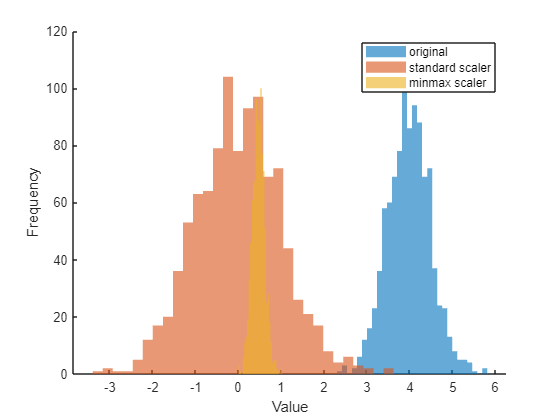

% Generate a random normally distributed array with 1000 values, a mean of 4, and standard deviation of 0.5
x = 0.5*randn(1000,1) + 4;  

% Scale the x distribution to have a mean of 0 and standard deviation of 1
y = (x - mean(x)) ./ std(x);

% Scale the x distribution to fit in the range 0 to 1
z = (x - min(x)) ./ (max(x) - min(x));

% Visualize the distributions
figure;
hold on
histogram(x,30, 'DisplayName', 'original', 'EdgeColor', 'none')
histogram(y,30, 'DisplayName', 'standard scaler', 'EdgeColor', 'none')
histogram(z,30, 'DisplayName', 'minmax scaler', 'EdgeColor', 'none')
xlabel('Value');
ylabel('Frequency');
hold off
legend('show');

**Sample Data**

Import sample data and split into training (80%) and testing (20%) sets. More information on [Splitting Data](https://apmonitor.com/pds/index.php/Main/SplitData) is available in another module. 

% Import the data from the url
data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');

% Split into nonrandom train and test subsets (train: 80%, test: 20%)
idx = floor(0.8*height(data))

idx = 2880

dataTrain = data(1:idx,:)

dataTrain = 2880×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

      0     0     0     16.06       16
      1     0     0     16.06    15.97
      2     0     0     16.06    16.03
      3     0     0     16.03       16
      4     0     0     16.03    15.94
      5     0     0     16.06       16
      6     0     0     16.03       16
      7     0     0     16.06    15.94
      8     0     0     16.06    15.97
      9     0     0     16.06    15.97
     10     0     0     16.06    15.94
     11     0     0     16.06    15.97
     12     0     0     16.06    15.97
     13     0     0     16.06    15.94
     14     0     0     16.06    15.94
     15     0     0     16.06    15.94


dataTest = data(idx+1:end,:)

dataTest = 721×5 table
    Time    Q1    Q2     T1       T2  
    ____    __    __    _____    _____

    2880    0     0     59.25    27.02
    2881    0     0     59.22    27.02
    2882    0     0     58.99    27.02
    2883    0     0     58.93    27.02
    2884    0     0     58.93    27.02
    2885    0     0     58.64    27.02
    2886    0     0      58.6    27.02
    2887    0     0      58.6    27.02
    2888    0     0     58.28    27.02
    2889    0     0     58.25    27.02
    2890    0     0     57.96    27.02
    2891    0     0     57.96    27.02
    2892    0     0     57.64    27.02
    2893    0     0      57.6    27.02
    2894    0     0     57.31    27.02
    2895    0     0     57.28    27.02


## Standard Scaler

The standard scaler transforms data *train* into a standard normal distribution from mean = x_bar

 and standard deviation σ to a new distribution with mean=0 and unit standard deviation (σ = 1). 

% Standardize train data
dataTrainNoTime = dataTrain{:,2:end}

dataTrainNoTime =          0         0   16.0600   16.0000
         0         0   16.0600   15.9700
         0         0   16.0600   16.0300
         0         0   16.0300   16.0000
         0         0   16.0300   15.9400
         0         0   16.0600   16.0000
         0         0   16.0300   16.0000
         0         0   16.0600   15.9400
         0         0   16.0600   15.9700
         0         0   16.0600   15.9700


% Standardize the data by using each value's z-score
s_train = zscore(dataTrainNoTime)

s_train =    -0.7483         0   -3.3534   -3.5218
   -0.7483         0   -3.3534   -3.5357
   -0.7483         0   -3.3534   -3.5078
   -0.7483         0   -3.3571   -3.5218
   -0.7483         0   -3.3571   -3.5496
   -0.7483         0   -3.3534   -3.5218
   -0.7483         0   -3.3571   -3.5218
   -0.7483         0   -3.3534   -3.5496
   -0.7483         0   -3.3534   -3.5357
   -0.7483         0   -3.3534   -3.5357


The scaling factors are available for each of the data columns.

% Get the standard deviation of each column of the data
a = std(dataTrainNoTime);
disp(['Scaler std: ' num2str(a)]);

Scaler std: 47.9799            0      8.10788      2.15281


% Get the mean of each column of the data
b = mean(dataTrainNoTime);
disp(['Scaler mean: ' num2str(b)])

Scaler mean: 35.9028            0      43.2491      23.5817


Scale the *test* data as well.

% Standardize test data
dataTestNoTime = dataTest{:,2:end}

dataTestNoTime =          0         0   59.2500   27.0200
         0         0   59.2200   27.0200
         0         0   58.9900   27.0200
         0         0   58.9300   27.0200
         0         0   58.9300   27.0200
         0         0   58.6400   27.0200
         0         0   58.6000   27.0200
         0         0   58.6000   27.0200
         0         0   58.2800   27.0200
         0         0   58.2500   27.0200


s_test = zscore(dataTestNoTime)

s_test =    -0.2872         0    2.8707    1.8271
   -0.2872         0    2.8674    1.8271
   -0.2872         0    2.8420    1.8271
   -0.2872         0    2.8353    1.8271
   -0.2872         0    2.8353    1.8271
   -0.2872         0    2.8033    1.8271
   -0.2872         0    2.7989    1.8271
   -0.2872         0    2.7989    1.8271
   -0.2872         0    2.7635    1.8271
   -0.2872         0    2.7602    1.8271


The above calculations require an array, not a table. Converting back to a table, the column labels can be reassigned.

s_train_df = array2table(s_train, "VariableNames", {'Q1' 'Q2' 'T1' 'T2'})

s_train_df = 2880×4 table
       Q1       Q2      T1         T2   
    ________    __    _______    _______

    -0.74829    0     -3.3534    -3.5218
    -0.74829    0     -3.3534    -3.5357
    -0.74829    0     -3.3534    -3.5078
    -0.74829    0     -3.3571    -3.5218
    -0.74829    0     -3.3571    -3.5496
    -0.74829    0     -3.3534    -3.5218
    -0.74829    0     -3.3571    -3.5218
    -0.74829    0     -3.3534    -3.5496
    -0.74829    0     -3.3534    -3.5357
    -0.74829    0     -3.3534    -3.5357
    -0.74829    0     -3.3534    -3.5496
    -0.74829    0     -3.3534    -3.5357
    -0.74829    0     -3.3534    -3.5357
    -0.74829    0     -3.3534    -3.5496
    -0.74829    0     -3.3534    -3.5496
    -0.74829    0     -3.3534    -3.5496


s_test_df = array2table(s_test, 'VariableNames', {'Q1' 'Q2' 'T1' 'T2'})

s_test_df = 721×4 table
       Q1       Q2      T1        T2  
    ________    __    ______    ______

    -0.28717    0     2.8707    1.8271
    -0.28717    0     2.8674    1.8271
    -0.28717    0      2.842    1.8271
    -0.28717    0     2.8353    1.8271
    -0.28717    0     2.8353    1.8271
    -0.28717    0     2.8033    1.8271
    -0.28717    0     2.7989    1.8271
    -0.28717    0     2.7989    1.8271
    -0.28717    0     2.7635    1.8271
    -0.28717    0     2.7602    1.8271
    -0.28717    0     2.7281    1.8271
    -0.28717    0     2.7281    1.8271
    -0.28717    0     2.6928    1.8271
    -0.28717    0     2.6883    1.8271
    -0.28717    0     2.6563    1.8271
    -0.28717    0      2.653    1.8271


## Min Max Scaler

An alternative to the standard scaler is the min-max scaler that adjusts all data between an upper and lower limit. This type of scaler is useful for machine learning algorithms that  require non-negative data or when the data set does not contain  outliers. Outliers skew most of the data to a very narrow region within the 0-1 interval.

% Min Max scale the training data
s_train_minmax = (s_train - min(s_train)) ./ (max(s_train) - min(s_train));
% Replace NaN values with 0
s_train_minmax(isnan(s_train_minmax)) = 0 

s_train_minmax =          0         0    0.0007    0.0090
         0         0    0.0007    0.0063
         0         0    0.0007    0.0117
         0         0         0    0.0090
         0         0         0    0.0036
         0         0    0.0007    0.0090
         0         0         0    0.0090
         0         0    0.0007    0.0036
         0         0    0.0007    0.0063
         0         0    0.0007    0.0063


% Repeat the same process for the test data
s_test_minmax = (s_test - min(s_test)) ./ (max(s_test) - min(s_test));
s_test_minmax(isnan(s_test_minmax)) = 0

s_test_minmax =          0         0    1.0000    0.9963
         0         0    0.9992    0.9963
         0         0    0.9933    0.9963
         0         0    0.9917    0.9963
         0         0    0.9917    0.9963
         0         0    0.9842    0.9963
         0         0    0.9832    0.9963
         0         0    0.9832    0.9963
         0         0    0.9749    0.9963
         0         0    0.9742    0.9963


## Exercise

The Temperature Control Lab [(TCLab)](https://apmonitor.com/heat.htm) has two heaters (*Q1* and *Q2*) and two temperature sensors (*T1* and *T2*). Heater 1 (*Q1*) is cycled between 0% and 100% and Heater 2 *Q2* is off as shown in the [Equipment Monitoring](https://apmonitor.com/pds/index.php/Main/ActuatorMonitor) exercise. A histogram plot shows the heaters and temperature distributions. 

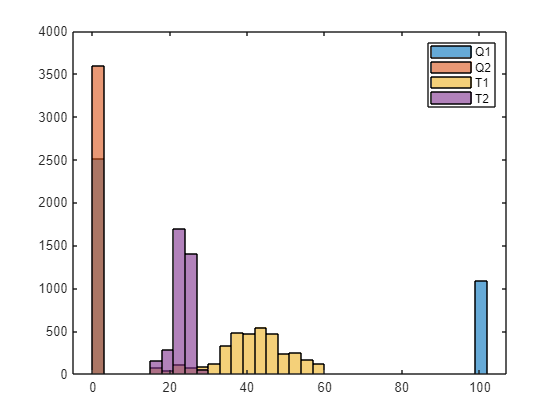

% Import data
data = readtable('http://apmonitor.com/pds/uploads/Main/tclab_data6.txt');
data = table2array(data);

% Visualize data
histogram(data(:,2),'BinWidth',3);
hold on
histogram(data(:,3),'BinWidth',3);
histogram(data(:,4),'BinWidth',3);
histogram(data(:,5),'BinWidth',3);

legend('Q1','Q2','T1','T2');
hold off

## Activities

**Scale Data**

Scale the [TCLab data](https://apmonitor.com/pds/uploads/Main/tclab_data6.txt) with a standard scaler and plot the distributions. 

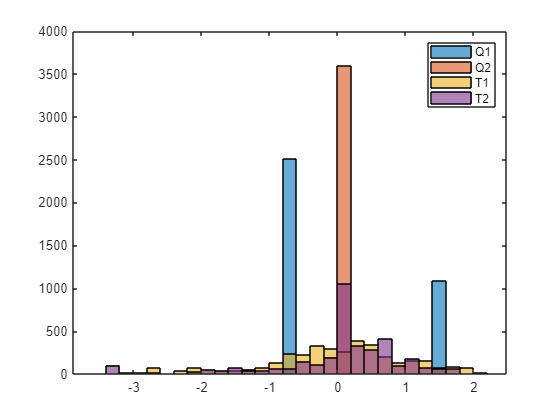

% Scale the data using z-score values
data_SS = zscore(data);

% Visualize the scaled data
histogram(data_SS(:,2),'BinWidth',0.2);
hold on
histogram(data_SS(:,3),'BinWidth',0.2);
histogram(data_SS(:,4),'BinWidth',0.2);
histogram(data_SS(:,5),'BinWidth',0.2);

legend('Q1','Q2','T1','T2');
hold off

**Neural Network with Scaled Data**

Train a [neural network](https://apmonitor.com/pds/index.php/Main/MultilayerPerceptronNeuralNetwork) to predict *T2* (output) from *Q1* and *T1* (input features). [Split the data](https://apmonitor.com/pds/index.php/Main/SplitData) into a train (80%) and test (20%) set. Create a parity plot of the predicted versus measured *T2*. 

% Set the random number generator seed to 0 (randomly generated numbers will remain the same between run throughs)
rng(0); 

% Get data
X = data;

% Set partition value for splitting the data
p = 0.2;

% Split the data into training and testing sets
cvp = cvpartition(size(X,1),'HoldOut',p);
X_train = X(cvp.training,:);
X_test = X(cvp.test,:);

% Standardize the data
X_train_input = zscore(X_train(:, [2,4]));
[Y_train, mu, sigma] = zscore(X_train(:, 5));

% Create neural network
hiddenLayerSizes = [6 6];
net = fitrnet(X_train_input, Y_train,'LayerSizes', hiddenLayerSizes);

% Test neural network
X_test_input = zscore(X_test(:,[2,4])); % Standardize test input data
X_test_predict = predict(net, X_test_input); % Run the neural network
X_test_predict = (X_test_predict * sigma) + mu; % Unstandardize the results

% Calculate R-squared
correlationMatrix = corrcoef(X_test(:,5), X_test_predict); % Get the correlation matrix between the predictions
correlationCoefficient = correlationMatrix(1, 2); % Get the value of the correlation between the predictions
rSquared = correlationCoefficient^2; % Square that value to get the R squared value
fprintf('R squared: %.2f', rSquared)

R squared: 0.67

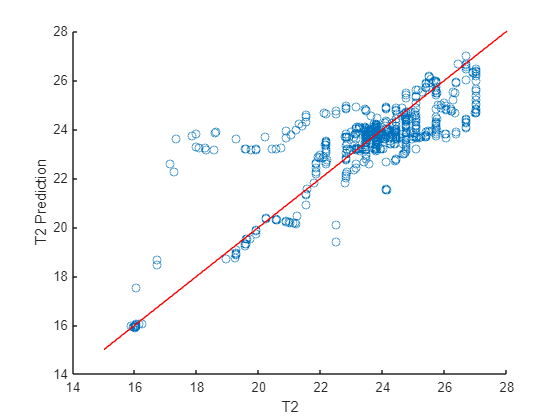

% Visualize the predicted versus real values
scatter(X_test(:,5), X_test_predict)
hold on
plot([15 28],[15 28],'r-')
xlabel('T2')
ylabel('T2 Prediction')
hold off

**Neural Network with Unscaled Data**

Repeat the *Neural Network with Scaled Data* activity but use unscaled data instead of scaled data  to perform the regression. Evaluate the neural network performance with a parity plot of the predicted and measured *T2* on the test set.

(Note: Failure to scale the data potentially results in parameters having an imbalanced weight due to difference in magnitude. Refer to the slight differences in the plots of Activity 2 and Activity 3.) 

% Set the random number generator seed to 0 (randomly generated numbers will remain the same between run throughs)
rng(0); 

% Get data
X = data;

% Set partition value for splitting the data
p = 0.2;

% Split the data into training and testing sets
cvp = cvpartition(size(X,1),'HoldOut',p);
X_train = X(cvp.training,:);
X_test = X(cvp.test,:);

% Create neural network
hiddenLayerSizes = [6 6];
X_train_input = X_train(:, [2,4]);
Y_train = X_train(:, 5);
net = fitrnet(X_train_input, Y_train,'LayerSizes', hiddenLayerSizes, 'Standardize', false);

% Test neural network
X_test_input = X_test(:,[2,4]);
X_test_predict = predict(net, X_test_input);

% Calculate R-squared
correlationMatrix = corrcoef(X_test(:,5), X_test_predict); % Get the correlation matrix between the predictions
correlationCoefficient = correlationMatrix(1, 2); % Get the value of the correlation between the predictions
rSquared = correlationCoefficient^2; % Square that value to get the R squared value
fprintf('R squared: %.2f', rSquared)

R squared: 0.55

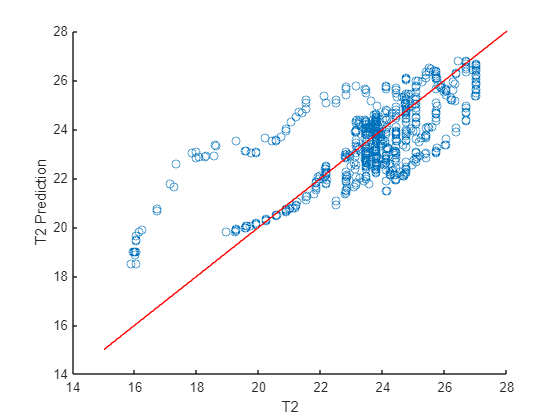


% Visualize the predicted versus real values
scatter(X_test(:,5), X_test_predict)
hold on
plot([15 28],[15 28],'r-')
xlabel('T2')
ylabel('T2 Prediction')
hold off

**Interactive Methods**

[Neural Net Fitting](https://www.mathworks.com/help/deeplearning/ref/neuralnetfitting-app.html) found under the APPS tab lets you create, visualize, and train a two-layer neural network for data fitting problems. 

[Normalize Data](https://www.mathworks.com/help/matlab/ref/normalizedata.html) found under Task in the LIVE EDITOR tab lets you interactively normalize data by choosing centering and scaling methods. 